## Dubins Path Computation

Helper script to compute shortest dubin's path. Define the test input.

startPose = [0, 0, pi/2];
goalPose = [1, 1, -pi/2];
minTurn = 2;

### This is showing the matlab's Dubin functionality (from robotics toolbox) - used as a reference to validate our implementation.

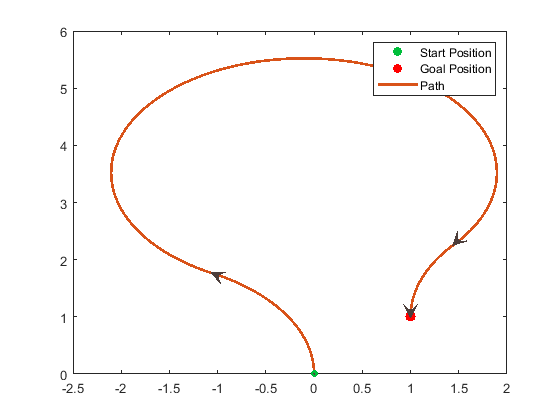

conn = robotics.DubinsConnection;
conn.MinTurningRadius = minTurn;
pathCalculator = connect(conn,startPose, goalPose);
pathSeg = pathCalculator{1};
show(pathSeg);

fprintf('path : %s\n', pathSeg.MotionLengths);

path : 2.154204e+00
path : 9.802011e+00
path : 1.364622e+00


fprintf('optimalMode : %s\n', strjoin(pathSeg.MotionTypes));

optimalMode : L R L


fprintf('optimalCost : %s\n', pathSeg.Length);

optimalCost : 1.332084e+01


### This is from our implementation. The values shown here should match the values shown above.

conn = DubinsConnection(minTurn, 0, false);
dubinsPathSegment = conn.computeDubinsPath(startPose, goalPose);
fprintf('path : %s\n', dubinsPathSegment.MotionLengths);

path : 1.077102e+00
path : 4.901005e+00
path : 6.823108e-01


fprintf('optimalMode : %s\n', dubinsPathSegment.MotionTypes);

optimalMode : LRL


fprintf('optimalCost : %s\n', dubinsPathSegment.Distance);

optimalCost : 6.660418e+00


path = dubinsPathSegment.PathPoses;

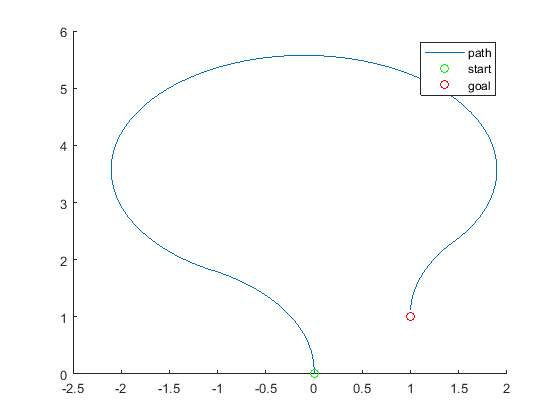

figure
hold on
plot(path(:, 1), path(:, 2))
plot(startPose(1), startPose(2), 'go')
plot(goalPose(1), goalPose(2), 'ro')
legend ('path', 'start', 'goal')
hold off

### This is interpolation from existing matlab classes...

  % Create a connection mechanism object
  turningRadius         = 1;
  numInterpolationSteps = 20;
  connectionDistance    = 10;

  connMech = matlabshared.planning.internal.DubinsConnectionMechanism;
  connMech.TurningRadius      = turningRadius;
  connMech.NumSteps           = numInterpolationSteps;
  connMech.ConnectionDistance = connectionDistance;

  % Find the Dubins distance between two poses
  d = connMech.distance(startPose, goalPose);

  % Find wayposes between two poses along Dubins curve.
  poses = connMech.interpolate(startPose, goalPose);
